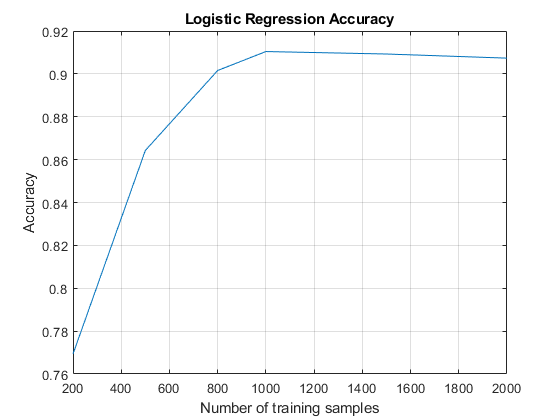

%Import the data
data = importdata("data.txt");
labels = importdata("labels.txt");

%Add a column of ones to the data
unos = ones(size(data, 1), 1);
labData = [data unos];

%Seperate out the test data.
testData = labData(2001:end,  :);
testLabel = labels(2001:end);

%Initialize n values to check accuracy
nVals = [200 500 800 1000 1500 2000];
accuracy = zeros(6, 1);

%Go through the different N values to see accuracy vs. number of rows
%provided.
for i=1:length(nVals)
    n = nVals(i);
    %Get the training data based on size of rows n.
    trainData = labData(1:n, :);
    trainLab = labels(1:n, :);
    %Calculate the weights
    w = logistic_train(trainData, trainLab);
    
    %Gets the accuracy using the testing data with the calculated weights.
    count = 0;
    for j=1:size(testData, 1)
        if -1*testData(j, :)*w >= 0 && testLabel(j) == 1
            count = count + 1;
        elseif -1*testData(j, :)*w < 0 && testLabel(j) == 0 
            if testLabel(j) == 0
                count = count + 1;
            end
        end
    end
    accuracy(i) = count/2601;
    
end

plot(nVals, accuracy);
title("Logistic Regression Accuracy")
xlabel("Number of training samples")
ylabel("Accuracy")
grid on

function [weights] = logistic_train(data, labels, epsilon, maxiter)
%
% code to train a logistic regression classifier
%
% INPUTS:
% data = n * (d+1) matrix with n samples and d features, where
% column d+1 is all ones (corresponding to the intercept term)
% labels = n * 1 vector of class labels (taking values 0 or 1)
% epsilon = optional argument specifying the convergence
% criterion - if the change in the absolute difference in
% predictions, from one iteration to the next, averaged across
% input features, is less than epsilon, then halt
% (if unspecified, use a default value of 1e-5)
% maxiter = optional argument that specifies the maximum number of
% iterations to execute (useful when debugging in case your
% code is not converging correctly!)
% (if unspecified can be set to 1000)
%
% OUTPUT:
% weights = (d+1) * 1 vector of weights where the weights correspond to
% the columns of "data"
%
    %If epsilon was not provided, then set default.
    if ~exist("epsilon", 'var')
        epsilon = 1e-5;
    end
    %If maxiter was not provided, then set default.
    if ~exist("maxiter", 'var')
        maxiter = 1000;
    end
    
    %Get the size of the data and the number of features.
    N = size(data, 1);
    J = size(data, 2);
    %Initialize the weights to 0.
    weights = zeros(J, 1);
    
    for i=1:maxiter
        %Store the old weights for later comparison.
        oldW = weights;
        grad = 0;
        %Compute the gradient for all the rows of the data 
        for j=1:N
            %Calculate the sigmoid for the gradient
            sig = 1/(1+exp(-data(j,:)*weights));
            grad = grad + (labels(j) - sig)*data(j, :)';
            
        end
        %Calculate the new weights.
        weights = epsilon*(-1/N * grad) + weights;
        
        %If the absolute difference of the weights averaged by the number
        %of features is less than epsilon, halt.
        difW = abs(sum(weights) - sum(oldW))/J;
        if difW < epsilon
            break
        end
    end
        
    
    
    
end